clear;clc;close all;
set(0,'defaultlinelinewidth',2)
set(0,'defaultaxeslinewidth',2);
set(0,'defaultaxesfontsize',30);
set(0,'defaulttextfontsize',30);
set(0,'DefaultLineMarkerSize',30);
set(0,'Defaultaxesfontname','Times New Roman');

# 5

% [x,y] = meshgrid(-0.1:0.01:0.1,-0.1:0.01:0.1);
% u = y.^2;
% v = x.^2;
% 
% figure
% quiver(x,y,u,v,2)
% xlabel('$u$','interpreter','latex');
% ylabel('$v$','interpreter','latex');
% xlim([-0.1 0.1])
% ylim([-0.1 0.1])
% set(gcf,'unit','centimeters','position',[20 20 20 20])
% saveas(gcf,'5','epsc')

# 4


$$J_m^{\prime } \left(x\right)=\frac{1}{2}\left\lbrack J_{m-1} \left(x\right)-J_{m+1} \left(x\right)\right\rbrack$$



max1 = 8;
r0 = 3.83;
d = 0.01;
N = max1/d;
theta= 0:2*pi/N:2*pi;
r1 = 0:d:r0;
psi1 = -besselj(1,r1);
r2 = r0+d:d:max1;
psi2 = -0.5*0.5*(besselj(0,r0)-besselj(2,r0))*(1-r0^2./r2.^2).*r2;

x = zeros(max1+1,max1+1);
y = zeros(max1+1,max1+1);
z = zeros(max1+1,max1+1);

psi = cat(2,psi1,psi2);
r = cat(2,r1,r2)

r =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900



for i = 1:N+1
    for j = 1:N+1
        x(i,j) = r(i)*cos(theta(j));
        y(i,j) = r(i)*sin(theta(j));
        z(i,j) = psi(i)*sin(theta(j));
    end
end

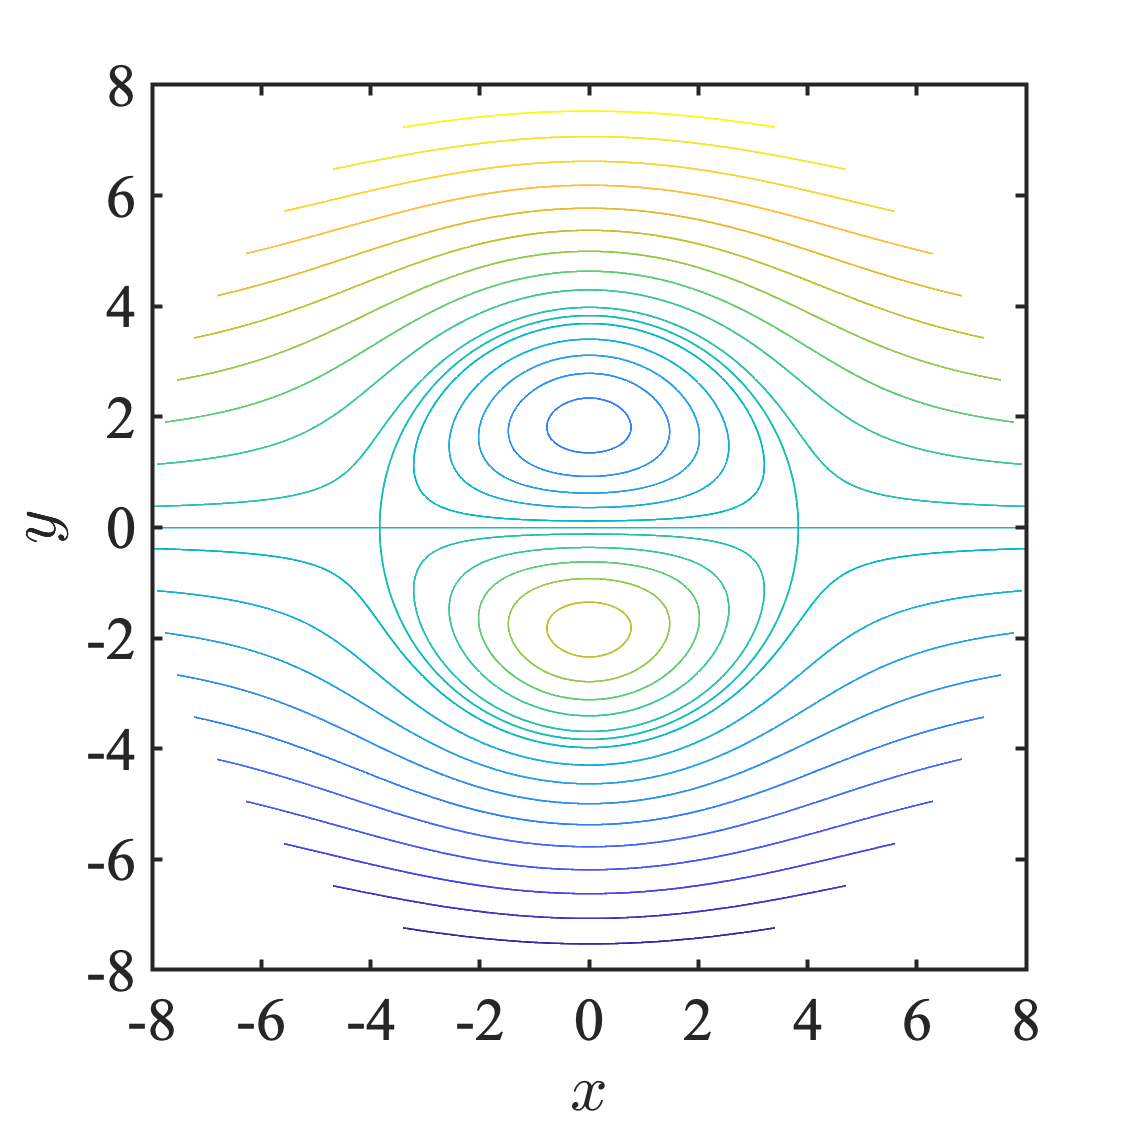

contour(x,y,z,1,'LineWidth',1)
hold on;
contour(-x,y,z,1,'LineWidth',1)
contour(x,y,z,20,'LineWidth',1)
hold off;

xlim([-8 8])
xticks(-8:2:8)
ylim([-8 8])
xlabel('$x$','interpreter','latex');
ylabel('$y$','interpreter','latex');
set(gcf,'unit','centimeters','position',[20 20 20 20])
saveas(gcf,'4','epsc')